# Trajectory Generation

## Load the map

map = load('trajectories/test_map.mat');
map = map.test_map;
Resolution=0.1; % meters
map = binaryOccupancyMap(map,Resolution);
uavRadius = .5;

% inflate map
inflate(map,uavRadius);
%save('trajectories/map', 'map');

## Create waypoints

start = [50 50];

waypoints = [[150 150]; ...
             [50 275]; ...
             [150 400]; ...
             [50 525]; ...
             [150 650]; ...
             [50 800]; ...
             [150 900]; ...
             [50 1000]; ...
             [150 1150]; ...
             [50 1250]; ...
             [150 1375]; ...
             [50 1500]];

## Visualize map and waypoints

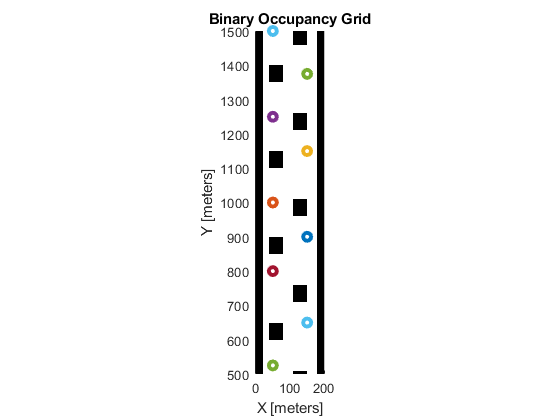

f1 = figure(1); clf;
hold on;
show(map);
ylim([500 1500])
plot(start(1), start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
end
hold off;

## Build PRM

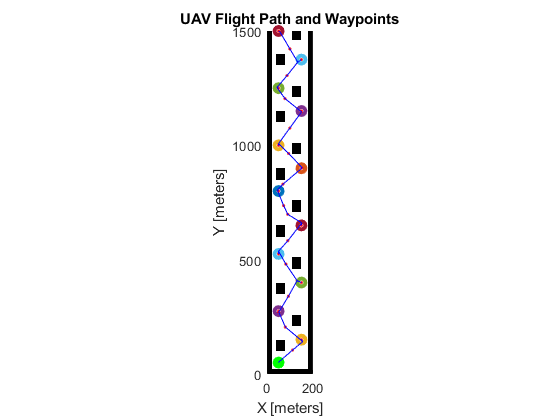

prm = mobileRobotPRM;
prm.Map = map;

prm.NumNodes = 5000;
prm.ConnectionDistance = 100;

path = findpath(prm, start, waypoints(1,:));
for i = 2:length(waypoints(:,1))
   p = findpath(prm, waypoints(i-1,:), waypoints(i,:));
   path = [path; p];
end
f2 = figure(2); clf;
hold on;
show(map);
plot(path(:,1), path(:,2), 'r.', 'MarkerSize', 5)
plot(start(1), start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(path-1)
    plot([path(i-1,1) path(i, 1)], [path(i-1,2) path(i, 2)], 'b');
end
hold off;
ylim([0 1500])
title("UAV Flight Path and Waypoints")

## Calculate flight parameters

desiredVelocity = 6; % m/s
path_distance = calculatedistance(path); % total distance to be covered
time_interval = calculatetime(path_distance,desiredVelocity); 
stoptimetotal = time_interval(2)+0.25*time_interval(2); % time to complete the mission
% generate smooth time stamped trajectory
sampletimetraj=.25; % 0.5 seconds by default
tSamples = sampletimetraj:sampletimetraj:time_interval(2);
[q,qd,qdd,pp] = bsplinepolytraj(path',time_interval,tSamples);
x_ref_points = [tSamples',q(1,:)'];
y_ref_points = [tSamples',q(2,:)'];


## Write trajectory data to db

% the database connection
conn = db_connect('nasadb');
write_trajectory_data;

trajectory_tb = 1×6 table
    path_distance    path_time                                            x_waypoints                                                                                           y_waypoints                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               

qer = "insert into trajectory_tb (path_distance, path_time, x_waypoints, y_waypoints) values (2143.72, 5.95, '{150.00, 50.00, 150.00, 50.00, 150.00, 50.00, 150.00, 50.00, 150.00, 50.00, 150.00, 50.00}', '{150.00, 275.00, 400.00, 525.00, 650.00, 800.00, 900.00, 1000.00, 1150.00, 1250.00, 1375.00, 1500.00}');"

## Load trajectory data

- Trajectories were loaded to a csv file from the database first

%trajectory_tb = sqlread(conn, 'trajectory_tb');
trajectory_tb = readtable('trajectories/trajectories.csv');
max_flight_time = 30.0;

trajectory_tb = trajectory_tb(trajectory_tb.path_time < max_flight_time, :);
trajectory_tb = sortrows(trajectory_tb, "path_time", 'descend');
% randomly select one of the top 3 missions, or the first
if height(trajectory_tb) > 3
    idx = randi(3,1);
else
    idx = 1;
end
trajectory = table2struct(trajectory_tb(4,:));
trajectory.x_waypoints = str2double(regexp(trajectory.x_waypoints,'[+-]?\d+\.?\d*','match'));
trajectory.y_waypoints = str2double(regexp(trajectory.y_waypoints,'[+-]?\d+\.?\d*','match'));
trajectory.x_ref_points = str2double(regexp(trajectory.x_ref_points,'[+-]?\d+\.?\d*','match'))';
trajectory.y_ref_points = str2double(regexp(trajectory.y_ref_points,'[+-]?\d+\.?\d*','match'))';
times = [1:1:length(trajectory.x_ref_points)]';
trajectory.x_ref_points = [times trajectory.x_ref_points];
trajectory.y_ref_points = [times trajectory.y_ref_points];
clear('trajectory_tb', 'times', 'idx');

max_flight_time = 18;
trajectory = get_trajectory('trajectories.csv', max_flight_time)

trajectory = struct with fields:
             Var1: 2
               id: 3
    path_distance: 1.3906e+03
        path_time: 17.8300
      risk_factor: 0.0100
     x_ref_points: [1069×2 double]
     y_ref_points: [1069×2 double]
      sample_time: 1
           reward: 1
        waypoints: [4×2 double]
